# Comaracion de Metodos de Integración Numerica

- Iniciamos el programa

- Cargamos datos

clear all,close all, clc
load("mediciones.mat")

- Extraemos los datos a leer y creamos sus varaiables de almacenamiento

t=transpose(medicion(:,2));     %Tiempo
f=transpose(medicion(:,1));     %Funcion a integrar
% t=linspace(0,2*pi,1000);
% f=sin(t);
[a,b]=size(f);                  %Tamaño de la funcion 
n=b-1;                         %intervalos
w=zeros(a,b);                   %vector a guardar la Integral en ceros
%w(1,1)=-1;

## Regla del Trapecio

for i=2:b-1
    w(1,i)=w(1,i-1)+trapecio_intg([t(1,i),t(1,i+1)],[f(1,i),f(1,i+1)],n);
end

%Plot funcion
plot(t,f,'b')
hold on
%Plot Integral numerica
plot(t(1,1:b-1),w(1,1:b-1),'r')

## Regla de Simpson 1/3

for i=2:b-2
    w(1,i)=w(1,i-1)+rule_simp13([t(1,i),t(1,i+1)],[f(1,i),f(1,i+1),f(1,i+2)],n);
end

hold on
%Plot Integral numerica
plot(t(1,1:b-2),w(1,1:b-2),'g')

## Regla de Simpson 3/8

for i=2:b-3
    w(1,i)=w(1,i-1)+rule_simp38([t(1,i),t(1,i+1)],[f(1,i),f(1,i+1),f(1,i+2),f(1,i+3)],n);
end

hold on
%Plot Integral numerica
plot(t(1,1:b-3),w(1,1:b-3),'k')

## Regla de Boole

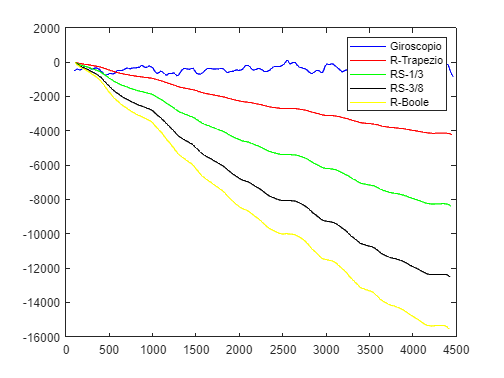

for i=2:b-4
    w(1,i)=w(1,i-1)+rule_boole([t(1,i),t(1,i+1)],[f(1,i),f(1,i+1),f(1,i+2),f(1,i+3),f(1,i+4)],n);
end

hold on
%Plot Integral numerica
plot(t(1,1:b-4),w(1,1:b-4),'y')
legend('Giroscopio','R-Trapezio','RS-1/3','RS-3/8','R-Boole')

%ylim([-20*10^5,5*10^5])